## State feedback for the AC generator

% Load your own arx models as returned by the arx function
% when you performed the system identification


J = 150;
w_g = 120*pi;
f = 200;
K = 2.6e3; % Max torque at 90 degree relative phase

% Choose the model to use for the design
mdl = arx221;

[num, den, h] = tfdata(mdl); % Get the polynomials and the sampling period
a = den{1};
b = num{1};
n = length(a)-1; % Model order



## Design


% Using controllable canonical form
Phi = [-a(2:end); eye(n-1), zeros(n-1,1)]

Phi =     1.9839   -0.9981
    1.0000         0


Gamma = [1;zeros(n-1,1)]

Gamma =      1
     0


C = b(2:end)

C = 1.0e-03 *

    0.2131    0.2000


D = 0;

sys = ss(Phi, Gamma, C, D, h)

sys =
 
  A = 
            x1       x2
   x1    1.984  -0.9981
   x2        1        0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
              x1         x2
   y1  0.0002131     0.0002
 
  D = 
       u1
   y1   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.



[ pole(sys), pole(mdl)] % Check that poles are the same

ans =    0.9920 + 0.1187i   0.9920 + 0.1187i
   0.9920 - 0.1187i   0.9920 - 0.1187i



% Controllability and observability
Ctr = ctrb(Phi, Gamma);
fprintf('Controllable = %d\n', rank(Ctr) == n);

Controllable = 1


Obs = obsv(Phi, C);
fprintf('Observable = %d\n', rank(Obs) == n);

Observable = 1


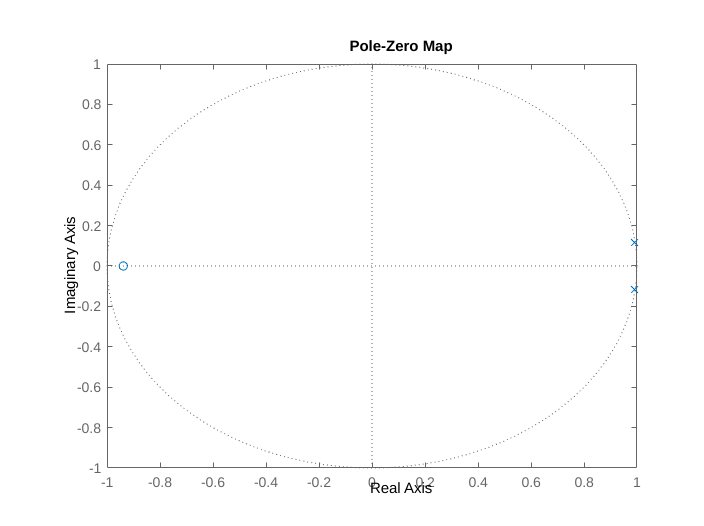



% Desired poles. Make some smart choices based on the poles of the
% plant. Let the closed-loop system have the same oscillatory modes
% (complex poles) as the plant, but better damped (as necessary).
figure()
pzmap(mdl)

pole(mdl)

ans =    0.9920 + 0.1187i
   0.9920 - 0.1187i


% Place two poles, ok damped
ts = 2;
zeta = 0.65;
wn = 4/ts/zeta

wn = 3.0769


pc1 = -zeta*wn + 1j*wn*sqrt(1-zeta^2);

pd1 = exp(pc1*h)

pd1 = 0.9597 + 0.0449i

pd2 = conj(pd1);
if n==2
    pd = [pd1, pd2];
elseif n==4
    pd = [pd1, pd2, pd1^2, pd2^2];
end


% State feedback gain
Lv = place(Phi, Gamma, pd);
%Lv = acker(Phi, Gamma, pd); % Only use acker if you have repeated poles

dcgn = C*( (eye(n) - (Phi-Gamma*Lv))\Gamma); % The DC gain
l0 = 1/dcgn;

% Observer poles. These should be faster (closer to the origin) than
% the closed-loop poles.
d = 2;
po = pd.^d;

% Deadbeat observer
%po = zeros(size(pd));

% Observer gain
%Kv = place(Phi', C', po)';
Kv = acker(Phi', C', po)';


% The closed-loop system. This consists of the states of the process model
% as well as the states of the observer.
% An output disturbance is included as an input in addition to the 
% reference signal
Phi_c = [Phi,  - Gamma*Lv
    Kv*C, Phi-Gamma*Lv-Kv*C];
Gamma_c = [l0*Gamma, zeros(n,1)
            l0*Gamma, Kv];
C_c = [C, zeros(1,n)];
sys_c = ss(Phi_c, Gamma_c, C_c, [D, 1], h)

sys_c =
 
  A = 
             x1        x2        x3        x4
   x1     1.984   -0.9981  -0.06443   0.07495
   x2         1         0         0         0
   x3   0.07481   0.07022     1.845   -0.9933
   x4   0.07557   0.07093    0.9244  -0.07093
 
  B = 
          u1     u2
   x1  8.807      0
   x2      0      0
   x3  8.807  351.1
   x4      0  354.6
 
  C = 
              x1         x2         x3         x4
   y1  0.0002131     0.0002          0          0
 
  D = 
       u1  u2
   y1   0   1
 
Sample time: 0.02 seconds
Discrete-time state-space model.



sys_d = ss(Phi_c, [zeros(n,1);Kv], C_c, 1, h);

## Check step responses and frequency properties

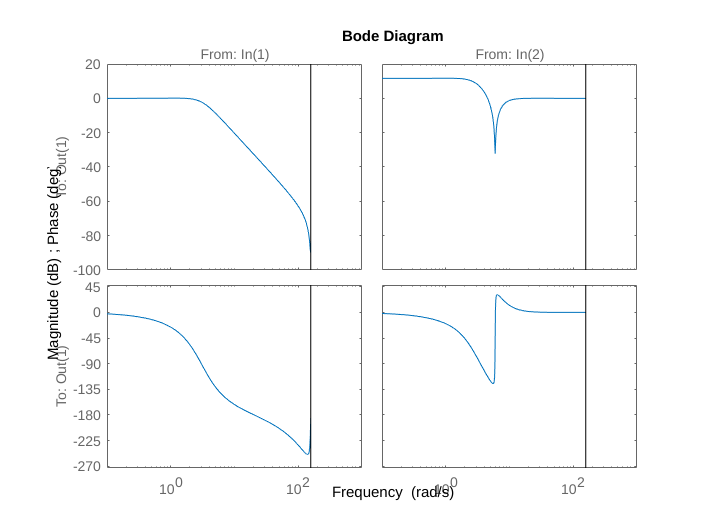

figure()
bode(sys_c)

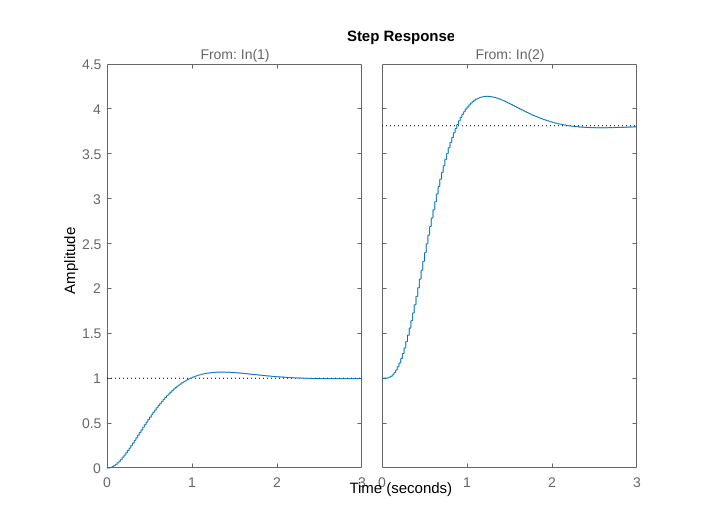

figure()
step(sys_c)

figure()
opts = bodeoptions

opts =

                   FreqUnits: 'rad/s'
                   FreqScale: 'log'
                    MagUnits: 'dB'
                    MagScale: 'linear'
                  MagVisible: 'on'
             MagLowerLimMode: 'auto'
                  PhaseUnits: 'deg'
                PhaseVisible: 'on'
               PhaseWrapping: 'off'
               PhaseMatching: 'off'
           PhaseMatchingFreq: 0
    ConfidenceRegionNumberSD: 1
                 MagLowerLim: -Inf
          PhaseMatchingValue: 0
         PhaseWrappingBranch: -180
                  IOGrouping: 'none'
                 InputLabels: [1×1 struct]
                OutputLabels: [1×1 struct]
                InputVisible: {'on'}
               OutputVisible: {'on'}
                       Title: [1×1 struct]
                      XLabel: [1×1 struct]
                      YLabel: [1×1 struct]
                   TickLabel: [1×1 struct]
                        Grid: 'off'
                   GridColor: [0.1500 0.1500 0.1500]
     

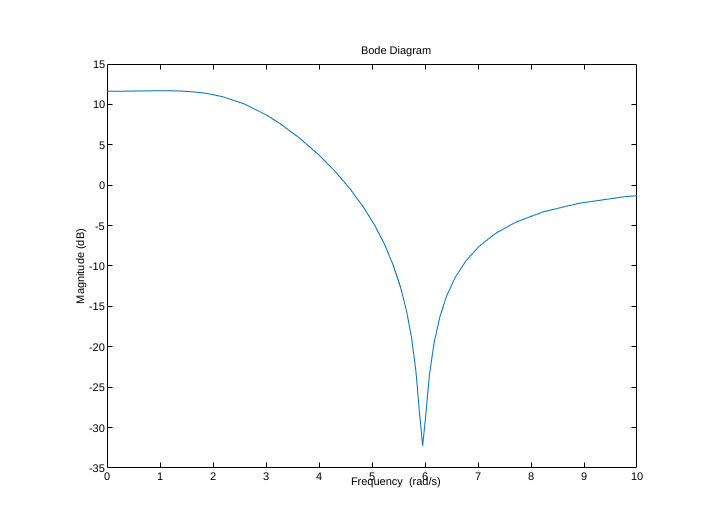

set(opts, 'FreqScale', 'linear')
set(opts, 'xlim', [0, 10])

bodemag(sys_d, opts)